clf
clear all

weatherData=readtable("STU-5-20241104211256.csv")%Weather Data for Day measurment taken

weatherData = 287×6 table
       Date       Time    Temp__F_    Pressure_mb_    Temp10m__F_    Temp2m__F_
    __________    ____    ________    ____________    ___________    __________

    11/04/0024    2100      51.4         1022.7            53           50.3   
    11/04/0024    2055      51.4         1022.7          53.3           50.4   
    11/04/0024    2050      51.6         1022.7          53.8           50.8   
    11/04/0024    2045        52         1022.7          53.8           51.3   
    11/04/0024    2040      52.3         1022.7          53.5           50.8   
    11/04/0024    2035      52.9         1022.7            55           51.5   
    11/04/0024    2030      52.7         1022.7          54.8           51.6   
    11/04/0024    2025      52.6         1022.6  

filename='Pressure 2024-11-04 20-44-24.xls';
data=readtable(filename);%Read Data 




pressures=data.Pressure_hPa_*100;%pressures from phone barometer in Pa
pressureTimes=data.Time_s_;%Times since start of pressure measurments

[groundTemp,groundPressure,lbArr]=getWeatherForMeasurment(filename,pressureTimes,weatherData);

Temp=[];%Tempeaturesfrom stanford weather station
calibrationPressure=[];%pressures from stanford weather station
calibrationAltidue=1;%altitude of the stanford weather station
lb=-.0065*ones(length(pressures),1);%Standard temperature lapse rate
R=8.31432;%universal gas constant
g=9.80665;%Gravity
M=0.0289644;%Molar mass of air
velos=getVelocities(pressures,groundTemp,lb,R,g,M,pressureTimes);
dAlt=changeInAltitude(pressures,groundTemp,lb,R,g,M);
veloPoly=polyfit(pressureTimes(1:end-1),velos,20);

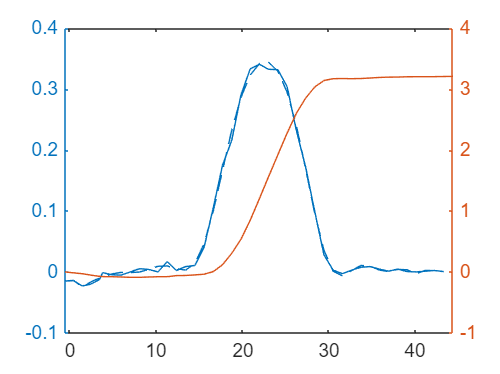

fitVelos=polyval(veloPoly,pressureTimes(1:end-1));

yyaxis left
plot(pressureTimes(1:end-1),velos)
hold on
plot(pressureTimes(1:end-1),fitVelos)
yyaxis right
plot(pressureTimes,dAlt)

function veloArray=getVelocities(pressure,temperature,lb,R,g,M,times)
    veloArray=zeros(length(pressure)-1,1);
    if isscalar(temperature)
        temperature=ones(length(pressure),1)*temperature;
    end
    if isscalar(lb)
        lb=ones(length(pressure),1)*lb;
    end
    for i=1:(length(pressure)-1)
    veloArray(i)=calculatVelo(pressure(i),pressure(i+1),temperature(i),lb(i),R,g,M,times(i+1),times(i));

    end

end

function velo=calculatVelo(p0,p1,temp,lb,R,g,M,t2,t1)
    velo=(temp/lb*((p1/p0)^(-R*lb/(g*M))-1))/(t2-t1);
end



function deltaAltitudeArray=changeInAltitude(pressure,temperature,lb,R,g,M)
    deltaAltitudeArray=zeros(length(pressure),1);
    p0=pressure(1);
    for i=1:length(temperature)
        deltaAltitudeArray(i)=calculateAlt(p0,pressure(i),0,temperature(i),lb(i),R,g,M);

    end

end

function altitude=calculateAlt(p0,p1,h0,temp,lb,R,g,M)
    altitude=h0+temp/lb*((p1/p0)^(-R*lb/(g*M))-1);
end

function [ambientTemp,ambientPressure,lbMat]=getWeatherForMeasurment(filename,readingTimes,weatherData)
    spaceIndex=strfind(filename," ");%get indecies for spaces in file name
    initTimeStr=string(extractBetween(filename, spaceIndex(end)+1, strfind(filename,".")-1));%Get End time of Measurments
    hour=str2num(extractBefore(initTimeStr,3))*60*60;
    minit=str2num(extractBetween(initTimeStr,4,5))*60;
    sec=str2num(extractAfter(initTimeStr,6));
    endTime=hour+minit+sec;
    startTime=endTime-readingTimes(end);
    ambientPressure=zeros(length(readingTimes),1);
    ambientTemp=zeros(length(readingTimes),1);
    lbMat=zeros(length(readingTimes),1);
    for i=1:length(readingTimes)
        timeFormatted=secondToTime(startTime+readingTimes(i));
        [closestTime, cIndex]=min(abs(weatherData.Time-timeFormatted));
        ambientTemp(i)=(weatherData.Temp__F_(cIndex)-32)*5/9+273.15;
        ambientPressure(i)=weatherData.Pressure_mb_(cIndex)*100;
        lbMat(i)=(((weatherData.Temp10m__F_(cIndex)-32)*5/9+273.15)-((weatherData.Temp2m__F_(cIndex)-32)*5/9+273.15))/(10-2);
    end

end

function closestMin=secondToTime(totalSec)
    h=floor(totalSec / 3600);
    m=floor(mod(totalSec, 3600) / 60);
    s=mod(totalSec, 60);
    closestMin=100*h+m+round(s/60);
end